# MATLABエージェントによるAlgorithm3の実装

clear all;
close all;
addpath('rl');

## 環境の宣言

A = [-1 2; 2.2 1.7];
B = [2; 1.6];
C = [1 2];
F = -1;

T = blkdiag(A, F);
B1 = [B; 0];
C1 = [C -1];

x0 = [5; -5; 5];

### 報酬関数の設計

Q = 6;
R = 1;

Q1 = C1'*Q*C1;

### 環境のインスタンス

env = rlDiscreteLQTEnv(A,B,C,F,Q,R,'x0',x0);
% rng(0)

## エージェントの作成

### エージェントオプションの作成

K0 = [0.3 1.3 0.75];
agentOpts = rlLQTAgentOptions('StepNumPerIteration', 20, 'DiscountFactor', 0.8, 'SaveExperiences', true);

### ノイズモデルの生成

agentOpts.NoiseOptions.Mean = 0;
agentOpts.NoiseOptions.Variance = 2;

### エージェントのインスタンス

agent = rlLQTAgent(getObservationInfo(env), getActionInfo(env), agentOpts,  [0.3 1.3 0.75]);

## エージェントの学習

trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',1, ...
    'MaxStepsPerEpisode',500, ...
    'StopTrainingCriteria', 'AverageSteps', ...
    'StopTrainingValue', 100000, ...
    'Verbose',true, ...
    'Plots','none');

trainingStats = train(agent,env,trainingOpts);

Episode:   1/  1 | Episode Reward : -305339765.22 | Episode Steps:  500 | Avg Reward : -305339776.00 | Step Count : 500


## 学習時の経験の取り出し

exps = agent.getExperiences();

## シミュレーション結果の検証

simOptions = rlSimulationOptions('MaxSteps', 100);
experience = sim(env,agent,simOptions);
totalReward = sum(experience.Reward)

totalReward = -8.5018e+03

gamma = agent.AgentOptions.DiscountFactor;
% gamma = agent.Gamma;

A = sqrt(gamma)*T;
B = sqrt(gamma)*B1;
S = 0;
Q = Q1;
R = R;
[P, Koptimal, ~] = idare(A, B, Q, R, [], []);

x0 = experience.Observation.AugumentStatesOfSystemDynamicsAndReferences.getdatasamples(1);
% 行動価値の評価
u = 1;
evaluate(agent.Critic, {x0, u})

ans = 1×1 の cell 配列
    {1×1 dlarray}


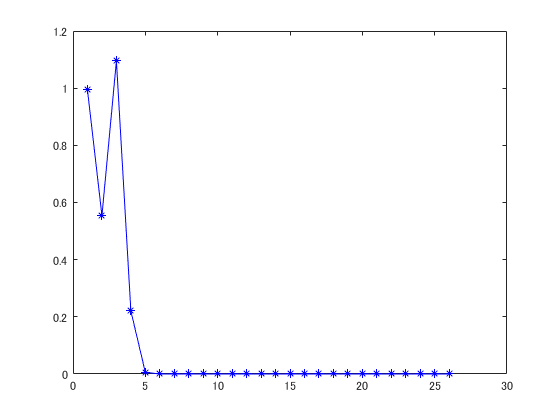

% number of gain updates
len = agent.KUpdate;
err = zeros(len,1);
for i = 1:len
    % norm of error in the gain
    err(i) = norm(agent.KBuffer{i}-Koptimal);
end  
plot(err,'b*-')

gainError = norm(agent.K - Koptimal)

gainError = 5.8083e-11

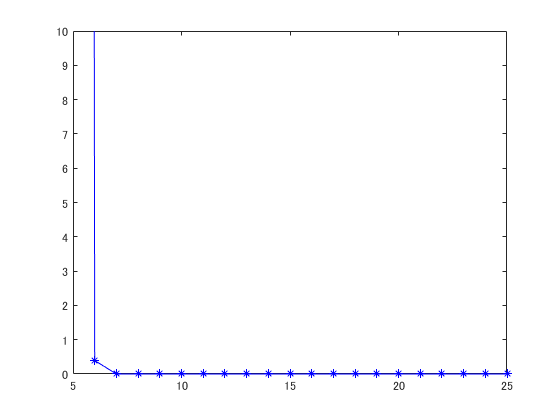

plot(agent.TDBuffer, '-b*');
ylim([0 10])

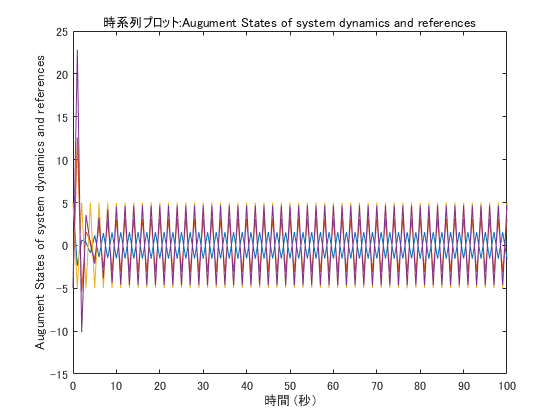


obs = experience.Observation.AugumentStatesOfSystemDynamicsAndReferences;
plot(obs);
X = squeeze(obs.Data);
y = C * X(1:2, :);
hold on;
plot(obs.Time, y);